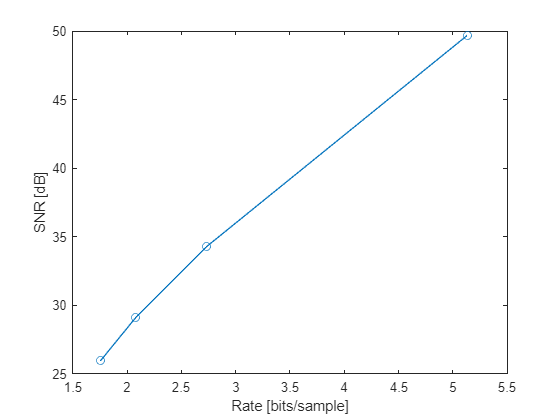

clear
clf()

hey = double(audioread("heyhey.wav"));

% Predictor size 1
rateSNRcurve(0.002:0.01:0.037, hey, findA(1,hey), "o")

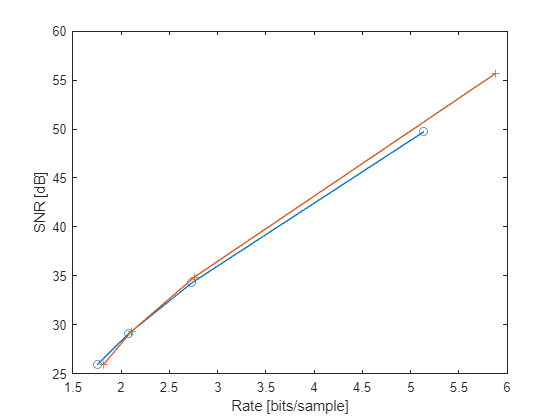

% Predictor size 2
hold on
rateSNRcurve(0.001:0.01:0.04, hey, findA(2,hey), '+')

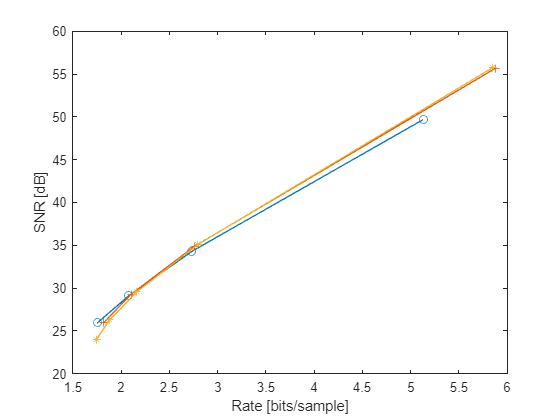

% Predictor size 3
rateSNRcurve(0.001:0.01:0.05, hey, findA(3,hey), "*")

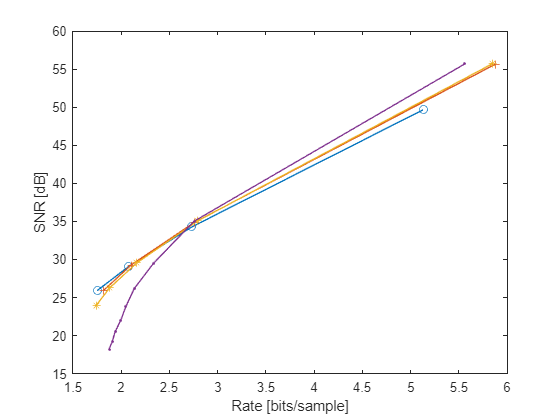

% Predictor size 4
rateSNRcurve(0.001:0.01:0.09, hey, findA(4,hey), ".")

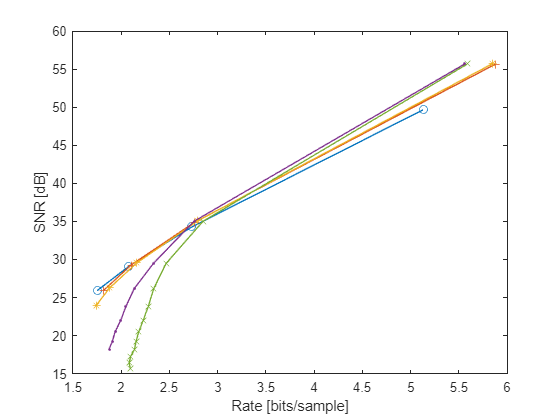

% Predictor size 5
rateSNRcurve(0.001:0.01:0.12, hey, findA(5,hey), "x")

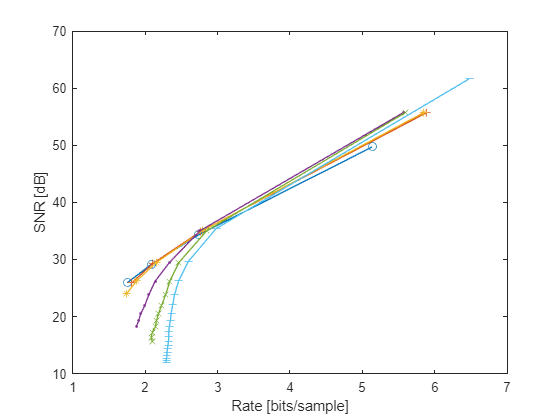

% Predictor size 6
rateSNRcurve(0.0005:0.01:0.19, hey, findA(6,hey), "_")

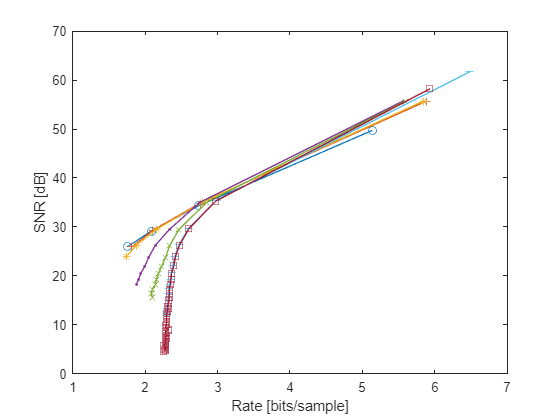

% Predictor size 7
rateSNRcurve(0.00075:0.01:0.5, hey, findA(7,hey), "square")

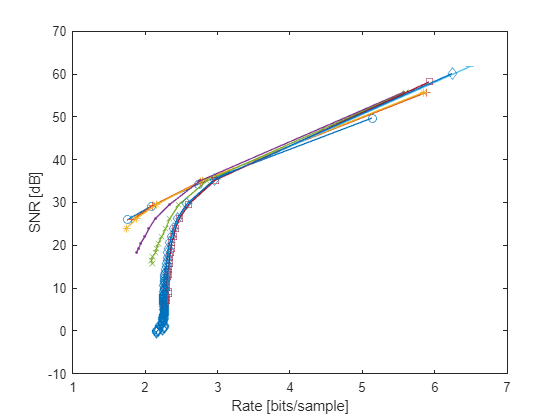

% Predictor size 8
rateSNRcurve(0.0006:0.01:1, hey, findA(8,hey), "diamond")

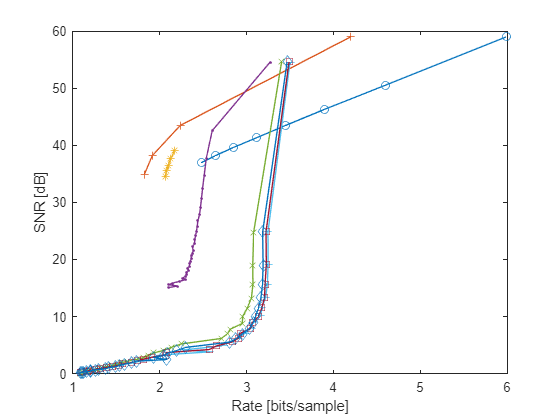

% NUIT

clear
hold off

clf()

hey = double(audioread("nuit.wav"));

% Predictor size 1
rateSNRcurve(0.0006:0.001:0.008, hey, findA(1,hey), 'o')
hold on

% Predictor size 2
rateSNRcurve(0.0006:0.001:0.01, hey, findA(2,hey), '+')

% Predictor size 3
rateSNRcurve(0.0006:0.001:0.01, hey, findA(3,hey), "*")

% Predictor size 4
rateSNRcurve(0.001:0.003:0.1, hey, findA(4,hey), ".")

% Predictor size 5
rateSNRcurve(0.001:0.03:1, hey, findA(5,hey), 'x')

% Predictor size 6
rateSNRcurve(0.001:0.03:1, hey, findA(6,hey), "_")

% Predictor size 7
rateSNRcurve(0.001:0.03:1, hey, findA(7,hey), "square")

% Predictor size 8
rateSNRcurve(0.001:0.03:1, hey, findA(8,hey), 'diamond')
beep


% Hey
[hey, Fs1] = audioread("heyhey.wav");
N= 8;
A3 = findA(N,hey);
hey = double(hey);
delta = 0.001; % steps 
[heyhat, q] = pred_coder(hey,A3, delta);
rate_hey = huffman(findRelFreq(q))
xhat_decoded_hey = pred_decoder(q,A3,delta);

audiowrite("hey_decoded.wav", xhat_decoded_hey, Fs1);

% Nuit
[nuit, Fs2] = audioread("nuit.wav");
N=8;
nuit = double(nuit);
delta = 0.01;
An = findA(N, nuit);
[~, q2] = pred_coder(nuit,An, delta);
rate_nuit = huffman(findRelFreq(q2))
xhat_decoded_nuit = pred_decoder(q2,An,delta);

audiowrite("nuit_decoded.wav", xhat_decoded_nuit, Fs2);




function SNR = findSNR(x, xhat)
    D = mean((x-xhat).^2);
    sigma2 = mean(x.^2);
    SNR = 10*log10(sigma2/D);
end

function rateSNRcurve(Steps, x, A, c)
    %Steps = 0.001:0.01:0.1;
    SNRVals = zeros(size(Steps));
    Rates = zeros(size(Steps));
    
    for i = 1:length(Steps)
        delta = Steps(i);
        [xhat, q] = pred_coder(x, A, delta);
        SNRVals(i) = findSNR(x, xhat);
        Rates(i) = huffman(findRelFreq(q));
    end
    
    SNRVals = flip(SNRVals);
    Rates = flip(Rates);
    
    plot(Rates, SNRVals, 'Marker', c)
    xlabel("Rate [bits/sample]")
    ylabel("SNR [dB]")
end